
syms r a
int(1/r,r,[0 a])

$$ans = \infty$$


syms f(r) a
assume(a>0)
f(r) = r*exp(-r/a)

$$f(r) = r\,{\mathrm{e}}^{-\frac{r}{a}}$$

f(inf)

$$ans = \mathrm{NaN}$$

syms a r
assume(a>0)
f(r) = a*exp(-r/a)

$$f(r) = a\,{\mathrm{e}}^{-\frac{r}{a}}$$

int(f,r,[0 inf])

$$ans = a^{2}$$

f(r) = -r*exp(-r/a)

$$f(r) = -r\,{\mathrm{e}}^{-\frac{r}{a}}$$

int(f,r,[0 inf])

$$ans = -a^{2}$$

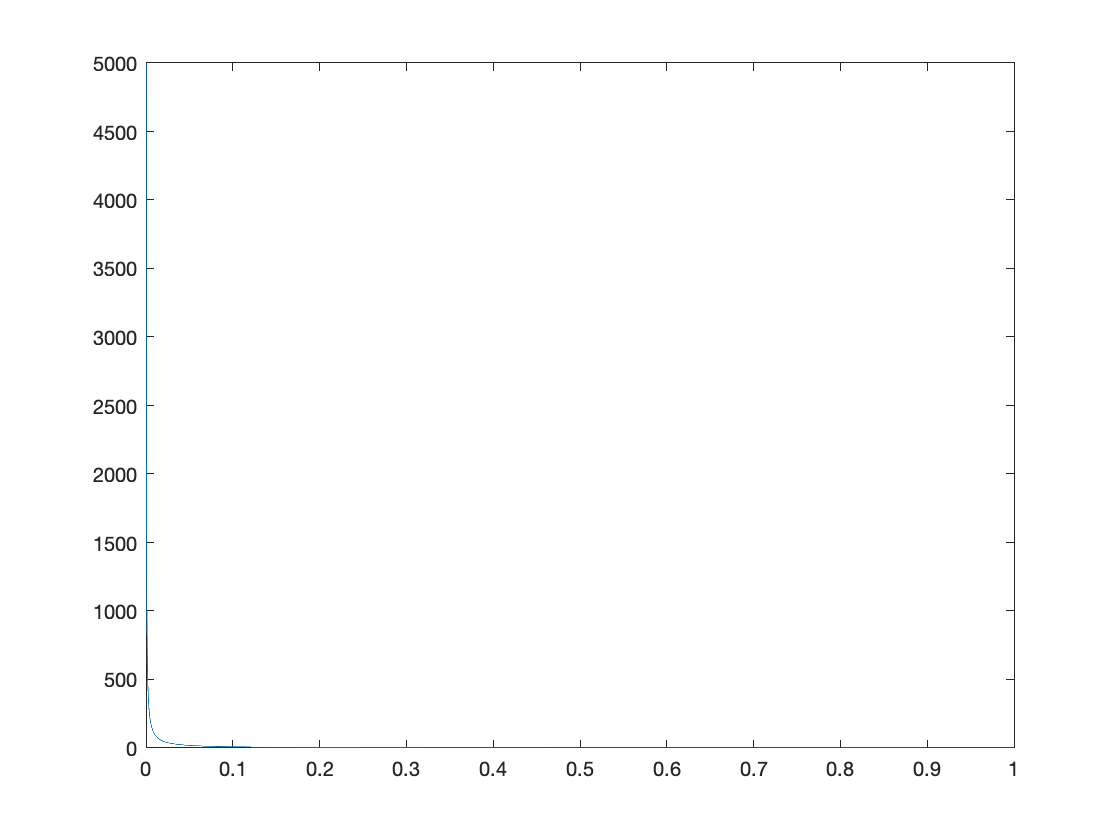

syms r theta phi a B
assume(a>0)

V = (B/r)*exp(-r/a)*[1 0 0];

E = -divergence_sym(V,[r theta phi],'Spherical');
E = simplify(E)*[1 0 0];
E = E(1);

V = subs(V(1),[a,B],[1,1]);
f = matlabFunction(V);

r = linspace(0,1,5000);
y = feval(f,r);
plot(r,y)

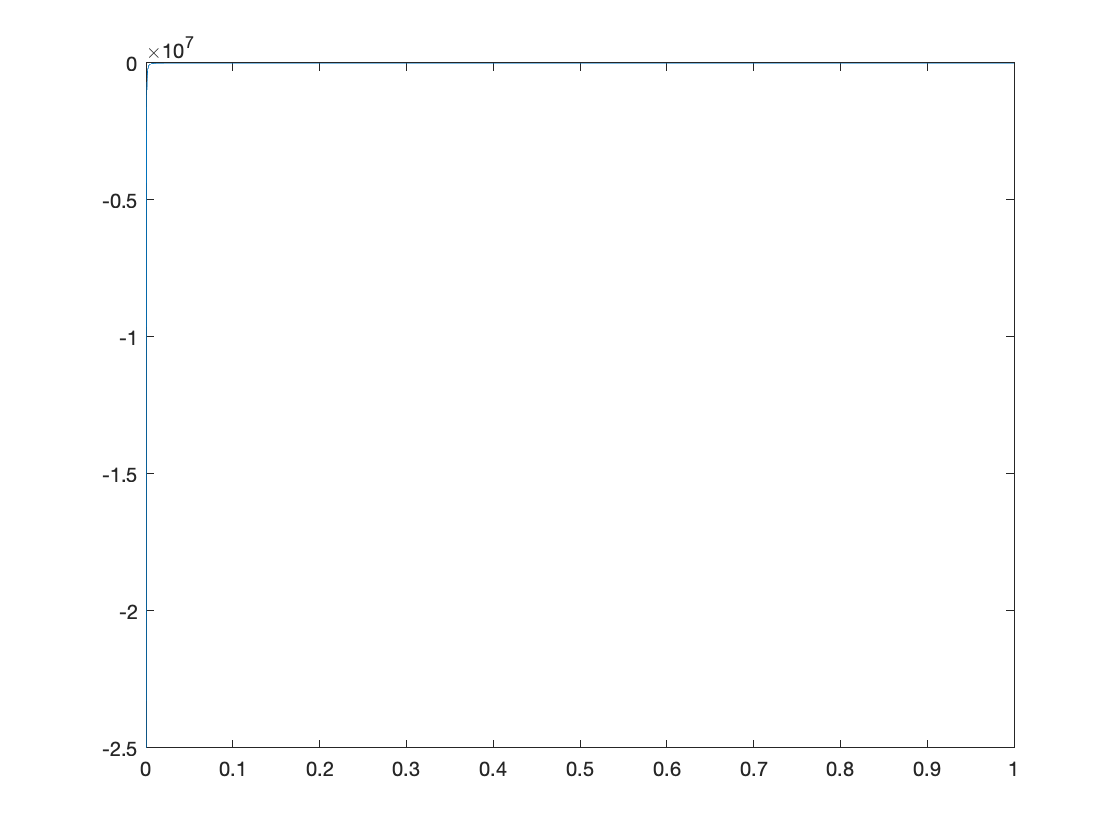


E = subs(E,[a,B],[1,1]);
f = matlabFunction(E);
%f = @(r) (exp(-r)/r.^2)*(r-1);
r = linspace(0,1,5000);
y = feval(f,r);
plot(r,y)

%div_E = divergence_sym(E,[r theta phi],'Spherical')
%simplify(div_E)

syms theta
f(theta) = sin(theta)/sqrt(1-cos(theta))
int(f,theta)

syms x z L R sigma epsilon_0 V
assume(R>0)
assume(z>0)

V = (sigma/(epsilon_0*2))*(sqrt(R^2+z^2) - z)
diff(V,z)
sin(0)^2

syms x y L

f = @(x,y) 1/sqrt(x^2+y^2)

f = function_handle with value:
    @(x,y)1/sqrt(x^2+y^2)


V = int(f,y)

$$V = \log\left(y+\sqrt{x^{2}+y^{2}}\right)$$

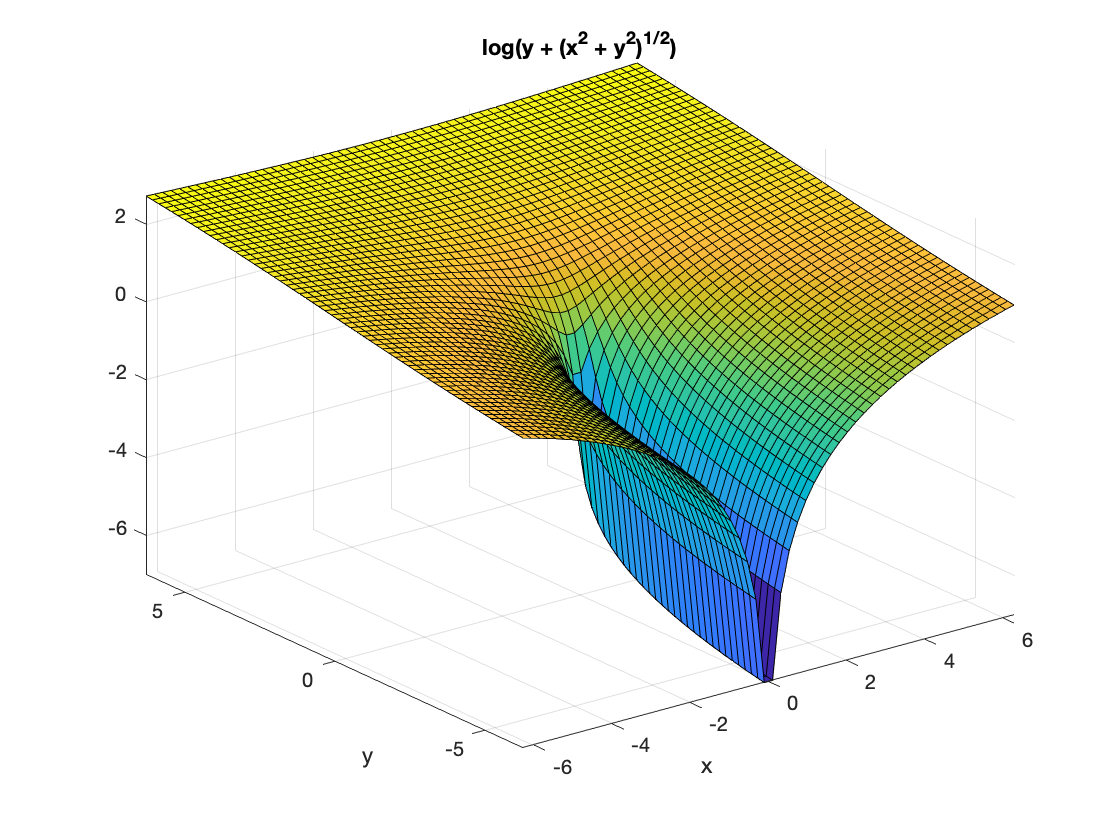

ezsurf(V)

% int(f,y,[0 R])

% HW1
syms E z a lambda epsilon_0 gamma
E = (lambda/(2*epsilon_0))*(1-z/(sqrt(a^2+z^2)))

$$E = -\frac{\lambda \,\left(\frac{z}{\sqrt{a^{2}+z^{2}}}-1\right)}{2\,\epsilon_{0}}$$

gamma = (2*epsilon_0)/lambda

$$gamma = \frac{2\,\epsilon_{0}}{\lambda }$$

E = E*gamma

$$E = 1-\frac{z}{\sqrt{a^{2}+z^{2}}}$$

E = subs(E, a, 1)

$$E = 1-\frac{z}{\sqrt{z^{2}+1}}$$

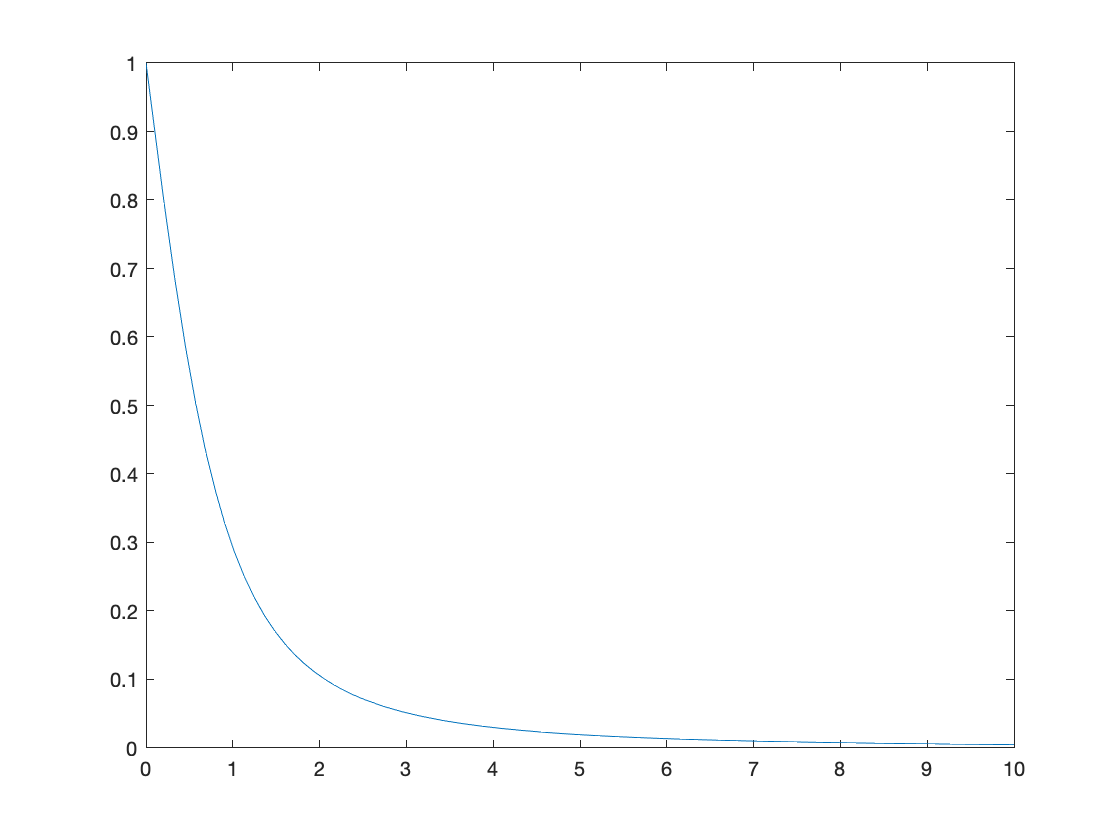

$$V = -\frac{\sigma \,\left(z-\sqrt{R^{2}+z^{2}}\right)}{2\,\epsilon_{0}}$$

$$ans = \frac{\sigma \,\left(\frac{z}{\sqrt{R^{2}+z^{2}}}-1\right)}{2\,\epsilon_{0}}$$

ans = 0

$$f(theta) = \frac{\sin\left(\theta \right)}{\sqrt{1-\cos\left(\theta \right)}}$$

$$ans(theta) = 2\,\sqrt{1-\cos\left(\theta \right)}$$

$$V = \left(\begin{array}{ccc} \frac{B\,{\mathrm{e}}^{-\frac{r}{a}}}{r} & 0 & 0 \end{array}\right)$$

$$E = -\frac{B\,{\mathrm{e}}^{-\frac{r}{a}}-\frac{B\,r\,{\mathrm{e}}^{-\frac{r}{a}}}{a}}{r^{2}}$$

$$ans = \frac{B\,{\mathrm{e}}^{-\frac{r}{a}}}{a\,r}-\frac{B\,{\mathrm{e}}^{-\frac{r}{a}}}{r^{2}}$$

$$ans = -\frac{B\,{\mathrm{e}}^{-\frac{r}{a}}\,\left(a-r\right)}{a\,r^{2}}$$

fplot(E,[0 10]) 

function Div = divergence_sym(V,X,coordinate_system)
switch coordinate_system
    case {'cartesian','Cartesian'}
        Div=divergence(V,X);
    case {'cylindrical','Cylindrical'}
        Div=1/X(1)*diff(X(1)*V(1),X(1))+...
          1/X(1)*diff(V(2),X(2))+...
            diff(V(3),X(3));
    case {'spherical','Spherical'}
    Div=1/X(1)^2*diff(X(1)^2*V(1),X(1))+...
    1/(X(1)*sin(X(2)))*diff(sin(X(2))*V(2),X(2))+...
    1/(X(1)*sin(X(2)))*diff(V(3),X(3));
end
end